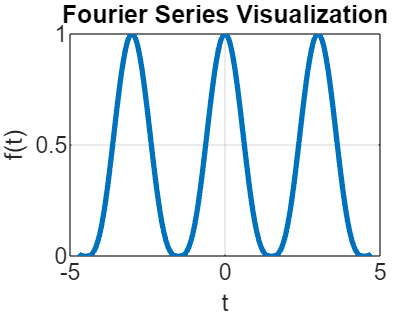

% Define the range of n values
n_values = -50:50;

% Define the range of t values
t_values = linspace(-3*pi/2, 3*pi/2, 1000);

% Initialize the Fourier series sum
fourier_series = zeros(size(t_values));

% Compute the Fourier series
for n = n_values
    if n ~= 0.5 && n ~= -0.5 && n ~= 1.5 && n ~= -1.5
        coefficient = 12 * (-1)^n / (pi * (1 - 4*n^2) * (9 - 4*n^2));
        fourier_series = fourier_series + coefficient * exp(1i * 2 * pi * n * t_values / 3);
    end
end

% Plot the real part of the Fourier series
figure;
plot(t_values, real(fourier_series), 'LineWidth', 2);
xlabel('t');
ylabel('f(t)');
title('Fourier Series Visualization');
grid on;